# LaserPulse class properties

Several physical properties of LaserPulse objects are automatically calculated and can be accessed using the dot notation.

As an example, create a new pulse in frequency domain

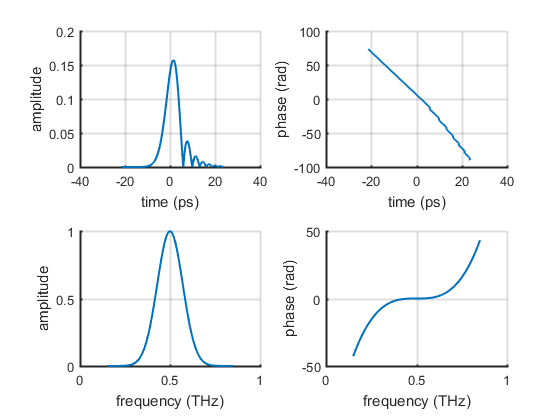

% frequency array
f = linspace(0, 10, 1000);
% electric field
Af = exp(-(f-0.5).^2/(0.1)^2);
phi = 1000*(f-0.5).^3;
% LaserPulse object
p2 = LaserPulse(f, 'THz', Af, phi);

% Plot the pulse
p2.plot();

Display some of the main properties of the laser pulse

s = sprintf('\ntime domain properties');
s = sprintf('%s\n----------------------', s);
propertyName = {'arrivalTime', 'duration', 'timeOffset', 'timeStep'};
for i = 1:numel(propertyName)
  s = sprintf('%s\n%s = %.2f %s', s, propertyName{i}, p2.(propertyName{i}), p2.timeUnits);
end
s = sprintf('%s\n\nfrequency domain properties', s);
s = sprintf('%s\n---------------------------', s);
propertyName = {'centralFrequency', 'bandwidth', 'frequencyOffset', 'frequencyStep'};
for i = 1:numel(propertyName)
  s = sprintf('%s\n%s = %.2f %s', s, propertyName{i}, p2.(propertyName{i}), p2.frequencyUnits);
end
fprintf(s);


time domain properties
----------------------
arrivalTime = 1.19 ps
duration = 4.68 ps
timeOffset = 1.21 ps
timeStep = 0.10 ps

frequency domain properties
---------------------------
centralFrequency = 0.50 THz
bandwidth = 0.12 THz
frequencyOffset = 5.01 THz
frequencyStep = 0.01 THz